# Module 6 Activity: Motor-clutch Dynamics and Cell Migration

version 1.2 (current as of 7/25/18)

Written by Brian Castle, University of Minnesota (email: cast0189@umn.edu)

## Goal:

The goal of this activity is to gain experience in coding a computational model for a cellular behavior, that is built on physical and chemical principles.  In this case we'll be simulating a motor-clutch system for cell traction dynamics as described by [Chan and Odde, Science, 2008](http://science.sciencemag.org/content/322/5908/1687.full).  The model will be built iteratively in much the same way that you would build a computational model from scratch.  Once we have working code, we'll then examine how our model can be used to gain insight into cellular behavior such as traction dynamics and migration. 

## Background and motivation:

At its most basic level, cancer progression is the combined dysregulation of cell division and cell migration. If malignant cells were capable only of proliferating and not migrating, then the resulting tumor would remain a local disease that could be effectively treated with existing local therapies, such as surgery and radiation.  What makes malignant tumors so deadly is that these hyper-proliferative cells can migrate away from the tumor mass and invade into the surrounding tissue, and, in many cases, metastasize to distant organs, which markedly reduces the efficacy of all therapies.  Indeed, it is a common paradigm in oncology that tumor spread is often a sign that the malignancy has become a terminal illness. In both invasion and metastasis, cell migration becomes a key driver of progression.

Cell migration is a multistep process that collectively integrates 1) cell membrane extension due to F-actin assembly, 2) formation and stabilization of attachments at the leading edge 3) acto-myosin contractility to destabilize focal adhesions, and 4) F-actin disassembly to complete the cycle (Figure 1 below).  Each step is a highly dynamic process involving active interaction between the cell cytoskeleton, cell surface, and extracellular matrix components.  Many studies (including the PSON data set) have shown that cell migration depends on several factors including extracellular adhesion proteins, the type of substrate cell are cultured on, as well as external chemical and mechanical cues. 

Figure 1 (from Alberts et al. *Molecular Biology of the Cell, Fifth Edition*, Garland Science 2008):

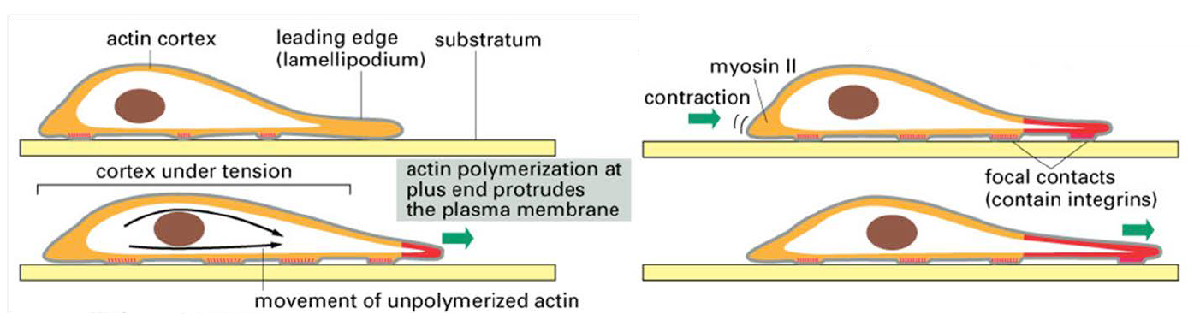

Because cells operate in an evironment where viscous forces dominate over inertia (low **Reynold's number**), they must constantly generate force in order to migrate.  Cells can transmit forces to their surroundings through a cellular motor-clutch system (described by [Mitchison and Kirschner, Neuron, 1988](https://www.sciencedirect.com/science/article/pii/0896627388901249?via%3Dihub)), where molecular clutches (i.e. cell adhesion proteins) link the F-actin cytoskeleton to the substrate and mechanically resist myosin motor-driven F-actin retrograde flow.  The system is analogous to a motor-clutch system in a vehicle, where the clutch acts as a link between the engine and the drive train.  In order to better understand cellular force-transmission dynamics, Chan and Odde (2008) built a simulation of a single force generating motor-clutch unit, as described below.

## Model description:

In the model (Figure 2 below), molecular clutches and the substrate are treated as simple, **Hookean springs**.  At every time step, myosin motors drive F-actin flow by exerting a force on an F-actin bundle. Next, individual molecular clutches are allowed to reversibly bind to the F-actin bundle with rate constants $k_{\mathrm{on}}$ and $k_{\mathrm{off}}$. Clutches that successfully engage will build tension with spring constant $\kappa_c$, as they are stretched by the motion of F-actin. Tension along the bound clutches increases their off-rate constant exponentially according to **Bell's Law**. Tension in the bound molecular clutches sums to a traction force that must be balanced by tension and deformation in the compliant substrate with spring constant $\kappa_{\mathrm{sub}}$.  As myosin motors work against this load, their motor sliding velocity is slowed according to a linear **force-velocity relation**.  

Figure 2 (from Chan and Odde, *Science*, 2008):

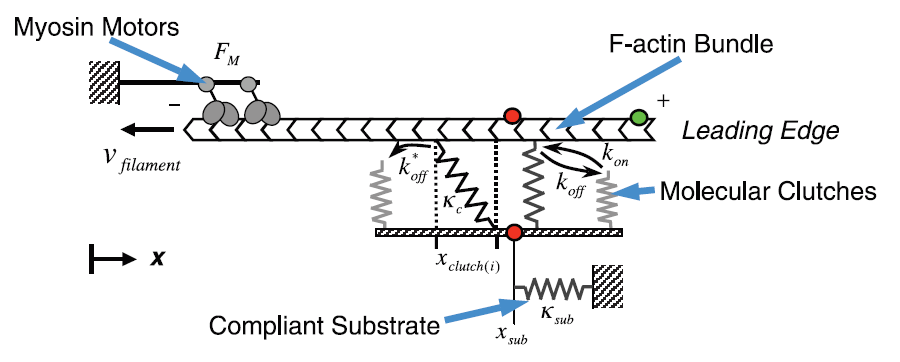

The model predicts two distinct regimes (Figure 3 below): (i) “frictional slippage,” on stiff substrates where molecular clutches rapidly unbind and are unable to develop enough load to produce large deformations and (ii) oscillatory “load-and-fail” dynamics, on soft substrates where the substrate is continuously deformed as load is built up in the system due to the binding of many clutches, eventually reaching a catastrophic point where the majority of clutches unbind in a very short period of time.

Figure 3 (from Chan and Odde, *Science*, 2008):

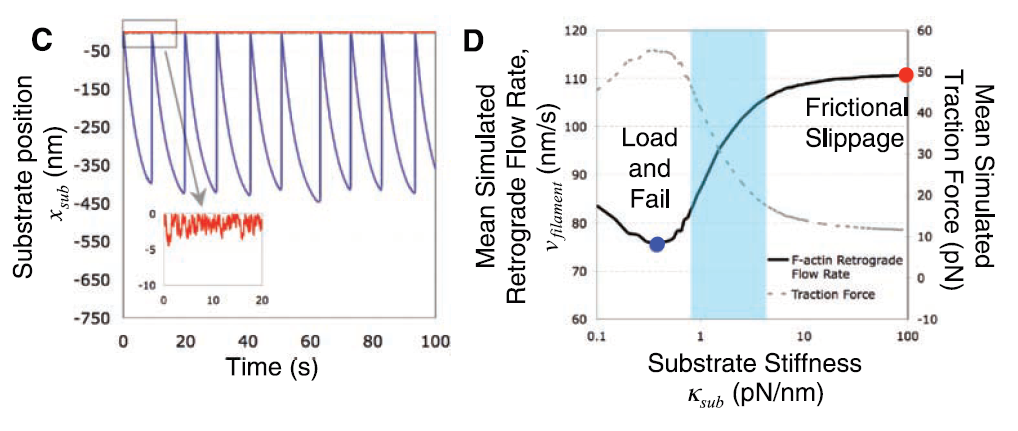

Since the original publication, other labs have now used and expanded the motor-clutch model to gain new and exciting insights into the traction force dynamics of cells!

See:  Elosegui-Artola et al., *Nat. Mater.*, 2014; Chaudhuri et al., *Nat. Comm.*, 2015; Elosegui-Artola et al., *Nat. Cell Biol.*, 2016; Sunyer et al., *Science*, 2016; Weinberg et al., *Biophys. J.*, 2017; Mekhdjian et al., *Mol. Biol. Cell*, 2017; Oria et al., *Nature*, 2017

## Parameter definition

To begin, we need to first define all of the constant parameters for the simulations.  Whenever possible, we want to set parameters to be consistent with measured values or value that are fit to experimental data.  But, rather than doing an extensive literature search or parameter sensitivity analysis we'll use the published values from Chan and Odde (2008).  For more information and references for where these parameters come from, refer to Table S1 in the Supplemental Material.

- Total number of myosin motors,    $n_m$ = 75

- Stall force for a single motor,   $F_m$ = -2 pN

- Unloaded myosin motor velocity,    $v_{\mathrm{motor}}$ = -120 nm/s

- Total number of clutches,    $n_c$ = 75

- Pseudo-first order clutch association rate,   $k_{\textrm{on},\mathrm{clutch}}$ = 1 ${\mathrm{s}}^{-1}$

- First-order clutch unloaded dissociation rate,   $k_{\textrm{off},\mathrm{clutch}}$ = 0.1 ${\mathrm{s}}^{-1}$

- Clutch spring constant,   $\kappa_{\mathrm{clutch}}$ = 5 pN/nm

- Compliant substrate spring constant,   $\kappa_{\mathrm{sub}}$ = 1 pN/nm

- Characteristic bond rupture force,     $F_b$ = -2 pN

Note, negative values reflect that the respective forces or movements are applied in the negative x-direction.  Using a negative value to define your parameters here will simplify your calculations later on in the code.  

**Note:** throughout the starter code you will see double exclamation marks "!!" and double percent signs "%%".  The double exclamation marks "!!" denote lines of code that require modification (parameter assignment, completed equation, logical condition, etc.).  While the double percent signs "%%" mark sections of code that are new.  As the code builds iteratively there will be some lines repeated multiple times from one section to the next.

%% Assign motor and clutch parameters using the values above (lines denoted with "!!" require modification)  
%% It is not necessary to change the units. 
motorNum = 75;%number of myosin motors
motorForce = -2;%pN, single motor stall force; use a negative value to denote that the force is applied in the negative x-direction
motorVel ;% !! nm/s, unloaded motor velocity; use a negative value as the motors pull actin in the negative x-direction
clutchNum ;% !! number of molecular clutches
clutchOn ;% !! s^-1, clutch on-rate constant
clutchOff ;% !! s^-1, clutch off-rate constant
clutchKs ;% !! pN/nm, clutch spring constant
bondForce ;% !! pN, bond rupture force

%% Assign substrate stiffness parameter
subKs ; % !! pN/nm, substrate spring constant

## Single clutch dynamics

Let's start by simulating the reversible binding of a single clutch.  For a single clutch the reaction scheme is as follows:

Eq. 1                                            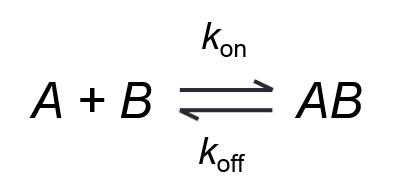

where *A *is ubound clutch, *B* is actin, and *AB* is bound clutch.  We can assume that [*B*] >> [*A*], such that $k_{\textrm{o}n,\mathrm{clutch}}$ is a pseudo-first order association rate, the product of $k_{\mathrm{on}}$ and [*B*] 

Additionally, remember that in *example3.mlx* we saw 

Eq. 2                                   $P\left(A\to \mathit{\text{AB}}\text{  }\text{in}\text{ }t\right)=1-\exp \left(-k_1 \left\lbrack B\right\rbrack t\right)$

Assign simulation parameter values.  For this initial simulation of a single clutch, we'll run for a total of 1000 steps with a time step 0.1 seconds.

%% Assign the simulation parameters.
timeStep ; % !! s, time step for simulation
numSteps ; % !! total number of steps to simulate

Initialize arrays used to keep track of simulation progress.

%Initializing arrays. No modifications are necessary here.
clutchState = 0; %denotes the state of the clutch; use 0 for unbound and 1 for bound
csArray = zeros(numSteps,1); %keeps track of the state of the clutch over the course of the simulation
timeArray = zeros(numSteps,1); %keeps track of elapsed time in the simulation

At this point it is a good idea to shuffle the random number generator since we are performing a Monte Carlo simulation.

rng('shuffle');  %shuffle random number generator

Now simulate the reversible binding kinetics for a single clutch, using a Monte Carlo approach.  For each time step you must:

- Check the current state of the clutch, bound or unbound

- Determine the probability that the clutch changes states and execute based on random number generation

- Record the elapsed time

- Record the clutch state at the current time point

%% Simulate a single clutch
for i = 2:numSteps %define the space over which to simulate
    if clutchState % !! clutch is unbound
        pBind ;% !! from Eq. 2, probability of binding within the given time step
        temp ; % !! generate random number
        if temp <= pBind %determine if the event is executed or not
            clutchState ; % !! clutch is now bound
        end
    elseif clutchState % !! clutch is bound
        pUnbind ;% !! from Eq. 2, probability of unbinding within the given time step
        temp ; % !! generate random number
        if temp <= pUnbind %determine if the event is executed or not
            clutchState ; % !! clutch is now unbound
        end
    end
    timeArray(i) = timeArray(i-1)+timeStep; %record the current time
    csArray(i) = clutchState; %record the clutch state
end

Now, let's plot the results.  No modification of the code is necessary here.

figure(1);clf
plot(timeArray,csArray,'b-')
axis([0 max(timeArray) -1 2])
xlabel('time (sec)','FontSize',12)
ylabel('clutch state (bound = 1, unbound = 0)','FontSize',12)

**Code Check: **

You should see multiple rounds of binding (value = 1) and unbinding of the clutch (value = 0).  If not, check your logicals in the if loop, making sure that the condition is changing when it binds or unbinds.  Also, check your probability equations (Eq. 2 above).

- Does the clutch spend more time bound or unbound? 

- Does this make sense based on the rate parameters defined above? Why or why not?

## Array of clutches

Now let's expand the system to include multiple clutches.  Because there are multiple clutches, we'll need an array to keep track of the individual states so *clutchState* has been switched to an array rather than a single value.  Additionally, *csArray* will now be used to keep track of the total number of bound clutches rather than the state of a single clutch. Also, change the time step to 10 milliseconds to get a better sense of the clutch dynamics

clutchState = zeros(clutchNum,1); %array to keep track of the state of each clutch; use 0 for unbound and 1 for bound
csArray = zeros(numSteps,1); %keeps track of the total number of bound clutches over the course of the simulation
timeArray = zeros(numSteps,1); %keeps track of elapsed time in the simulation

timeStep ; % !! s, time step for simulation

Use the starter code below to construct the main loop of the simulation. The event sequence is the same as for a single clutch, however, you'll now need to loop through each individual clutch, performing step (1) and (2) for each

for i = 2:numSteps %define the space over which to simulate
    %% second for loop to simulate multiple clutches has been added
    for n = 1 % !! loop through each individual clutch
        if  clutchState(n) % !! clutch is unbound
            pBind ;% !! from Eq. 2, probability of binding within the given time step
            temp ; % !! generate random number
            if temp <= pBind %determine if the event is executed or not
                clutchState(n) ; % !! clutch is now bound
            end
        elseif clutchState(n) % !! clutch is bound
            pUnbind ;% !! from Eq. 2, probability of unbinding within the given time step
            temp ; % !! generate random number
            if temp <= pUnbind %determine if the event is executed or not
                clutchState(n) ; % !! clutch is now unbound
            end
        end
    end
    
    timeArray(i) = timeArray(i-1)+timeStep; %record the current time
    csArray(i) = sum(clutchState); %record the total number of bound clutches
end

Now, let's plot the results.  No modification of the code is necessary here.

figure;clf
plot(timeArray,csArray,'b-')
axis([0 max(timeArray) 0 max(csArray)+2])
xlabel('time (sec)','FontSize',12)
ylabel('number of bound clutches','FontSize',12)

**Code Check: **

You should see that the number of bound clutches initially rises quickly and then approaches a steady state number.  If not, check your for loop conditions to be sure that you are looping through all the clutches.

- How long does it take for the clutch dynamics to reach steady state? How many clutches are bound, on average, at steady state? 

- Does this make sense based on the rate parameters for the clutches defined above? Why or why not?

## Balance the Forces

Now that you have code that simulates the dynamics of an array of clutches, you've already completed a big chunk of the model! 

Once the clutch network has been resolved, as described in Chan and Odde, 2008, the forces are balanced to solve for the position of the substrate.  The force balance states that the sum off all forces must equal zero (Newton's Third Law of Motion).  Therefore, 

Eq. 3                                           $F_{\mathrm{clutch}} =F_{\mathrm{sub}}$

Each clutch, as well as the substrate, is treated as a **Hookean spring** such that $F=-\kappa x$.  The system of clutches is treated as springs in parallel, so the forces sum.  Thus from Eq. 3 we have

Eq. 4                    $-\sum_{i=1}^{n_b } \kappa_{\mathrm{clutch}} \cdot \left(x_{\mathrm{clutch}} -x_{\mathrm{sub}} \right)=-\kappa_{\mathrm{sub}} x_{\mathrm{sub}}$

where $n_b$ is the number of bound clutches (note, unbound clutches do not contribute any force), and $\kappa$ and $x$ are the spring constant and position of the clutches and substrate, respectively.  Solving Eq. 4 for $x_{\mathrm{sub}}$, we get

Eq. 5                                $x_{\mathrm{sub}} =\frac{\kappa_{\mathrm{clutch}} \cdot \sum_{i=1}^{n_{\mathrm{eng}} } x_i }{\kappa_{\mathrm{sub}} +n_{\mathrm{eng}} \cdot \kappa_{\mathrm{clutch}} }$

Clutches are loaded when they bind to actin and are pulled towards the cell body due to myosin-mediated retrograde flow.  For now, we'll assume that actin moves at constant velocity, defined by the unloaded motor velocity, such that $v_{\mathrm{actin}} =v_{\mathrm{motor}}$.  The position of bound clutches then moves according to

Eq. 6                        $x_{\text{clutch}} \left(t\right)=x_{\text{clutch}} \left(t-\Delta t\right)+v_{\text{actin}} \cdot \Delta t$

So, now, for each time step you'll need to add code to 

-  Solve for the substrate position ($x_{\mathrm{sub}}$).  

- Update the position of each clutch ($x_{\mathrm{clutch}}$).  Assume that the position of each unbound clutch is the substrate position (i.e. $x_{\mathrm{clutch}} =x_{\mathrm{sub}}$ for unbound clutches).

Initialize arrays.  We've now added arrays to keep track of the clutch and substrate positions.

% Initialize arrays.  No modification of the code is necessary here.
clutchState = zeros(clutchNum,1); %array to keep track of the state of each clutch; use 0 for unbound and 1 for bound
clutchPos = zeros(clutchNum,1); %array to keep track of the position of each individual clutch
csArray = zeros(numSteps,1); %keeps track of the total number of bound clutches over the course of the simulation
timeArray = zeros(numSteps,1); %keeps track of elapsed time in the simulation
subPos = zeros(numSteps,1); %array to keep track of the position of the substrate at each time point

for i = 2:numSteps %define the space over which to simulate
    for n = 1 % !! loop over each individual clutch
        if  clutchState(n) % !! clutch is unbound
            pBind ;% !! from Eq. 2, probability of binding within the given time step
            temp ; % !! generate random number
            if temp <= pBind %determine if the event is executed or not
                clutchState(n) ; % !! clutch is now bound
            end
        elseif clutchState(n) % !! clutch is bound
            pUnbind ;% !! from Eq. 2, probability of unbinding within the given time step
            temp ; % !! generate random number
            if temp <= pUnbind %determine if the event is executed or not
                clutchState(n) ; % !! clutch is now unbound
            end
        end
    end
    
    csArray(i) = sum(clutchState); %record the total number of bound clutches
    
 
    %% Balance the forces to determine the substrate position
    sumClutchPos = sum(clutchPos(clutchState==1)); %summation from Eq. 5 numerator (note: this is the summation only, not complete numerator), do not change
    subPos(i) = (sumClutchPos)/(subKs+(csArray(i))); %from Eq. 5, solve for the substrate position
    
    %% determine actin flow rate
    actinFlow ; % !! actin flow rate, for now assume it is equal to the unloaded motor velocity
    
    %% loop through each clutch and update the position
    for n = 1:clutchNum
        if clutchState(n) % !! clutch is unbound
            clutchPos(n) ; % !! unbound clutches are set at the substrate position
        elseif clutchState(n) % !! clutch is bound
            clutchPos(n) = clutchPos(n); % !! position moves at constant velocity (hint: actin flow rate)
        end
    end
    
    timeArray(i) = timeArray(i-1)+timeStep; %record the current time
end

Let's take a look at the results.  No modification is necessary here

figure;
subplot(2,1,1)
plot(timeArray,csArray,'b-')
axis([0 max(timeArray) 0 max(csArray)+2])
xlabel('time (sec)','FontSize',12)
ylabel('number of bound clutches','FontSize',12)
subplot(2,1,2)
plot(timeArray,subPos,'b-')
axis([0 max(timeArray) min(subPos) 0])
xlabel('time (sec)','FontSize',12)
ylabel('substrate position (nm)','FontSize',12)

**Code Check:**

The clutch dynamics should appear similar to the section above since we haven't changed this part of the code.  However, now you should see that the motor and clutch dynamics load the substrate, pulling it at an approximately constant rate in the negative x-direction.  If not, check how the position is updated when the clutch is bound.

- Approximate by eye the rate at which the substrate is moved (slope of the line).  Is this what you'd expect based on the velocity at which the motors step?  Why or why not?

There's a problem here though, the substrate is an elastic material and is not infinitely extensible.  As the substrate is deformed, it will apply a resistive force against the motors and clutches.  Let's now add this force feedback in with the next step.

## mini-DREAM Challenge Exercise

## Clutch Force Feedback

Up until this point we've assumed that the force does not feed back into the dynamics of the system, that the actin flow rate and the clutch dissociation rate is constant in time.  However, as load is built within the system, that load will affect these processes.

The clutch dissociation rate will depend on the load that it is under according to **Bell's law**, such that 

Eq. 7                                        $k_{\mathrm{off}} '=k_{\mathrm{off}} \cdot \mathrm{exp}\left(F_{\mathrm{clutch}} /F_b \right)$

where $k_{\mathrm{off}} \text{ }$is the unloaded dissociation rate, $F_b$ is the rupture force for the bond, and $F_{\mathrm{clutch}}$ is the tension within an individual clutch given by 

Eq. 8                                         $F_{\mathrm{clutch}} =\kappa_{\mathrm{clutch}} \cdot \left(x_{\mathrm{clutch}} -x_{\mathrm{sub}} \right)$

The more the clutch (spring) is extended, the higher the force, and the higher the off-rate.

The actin flow rate will also depend on the load that has built up, specifically that being placed on the myosin motors.  As more clutches bind, the system applies load on the myosin motors, slowing their velocity (and similarly the actin flow rate), referred to as a force-velocity relationship.  We define this force-velocity relationship as 

Eq. 9                                        $v_{\mathrm{actin}} =v_{\mathrm{motor}} \left(1-\frac{\kappa_{\mathrm{sub}} \cdot x_{\mathrm{sub}} }{F_{\mathrm{stall}} }\right)$

where $F_{\mathrm{stall}}$ is the stall force of the motors, the maximum force that the motors are able to resist.  You may note that according to Eq. 9, the actin flow rate becomes 0 when the force on the substrate is equal to the stall force, i.e. it stalls out.  The stall force is given by 

Eq. 10                                                    $F_{\mathrm{stall}} =n_m F_m$

where $n_m$ is the total number of myosin motors and $F_m$ is the force required to stall the activity of a single myosin motor.

For this section you will now add the feedback of force into the dynamics of the system. 

- For each bound clutch, solve for the dissociation rate based on the force that is being applied

- Adjust the actin flow rate based on the load that has buit up in the system

Initialize arrays.  Arrays to keep track of the actin flow rate and the force on the individual clutches have been added.  As load is built up in the system, the off-rate of clutches will increase, since we don't want to miss any of these events, let's make the time step smaller and run for more steps.  Use a time step of 1 millisecond and simulate for a total of 10 seconds (10,000 total steps).

%% change the number of steps and time step
timeStep ; %!! s, time step for simulation
numSteps ; %!! total number of steps to simulate

%initialize arrays, no modification necessary here
clutchState = zeros(clutchNum,1); %array to keep track of the state of each clutch; use 0 for unbound and 1 for bound
clutchPos = zeros(clutchNum,1); %array to keep track of the position of each individual clutch
clutchForce = zeros(clutchNum,1); %array to keep track of the amount of force on each clutch
csArray = zeros(numSteps,1); %keeps track of the total number of bound clutches over the course of the simulation
timeArray = zeros(numSteps,1); %keeps track of elapsed time in the simulation
subPos = zeros(numSteps,1); %array to keep track of the position of the substrate at each time point
actinFlow = zeros(numSteps,1); %array to keep track of the actin flow rate in time

For this activity, we'll do something a bit different. Complete the section of code below, then copy and paste the code to the Synapse discussion thread titled "Module 6 exercise code" ([link](https://www.synapse.org/#!Synapse:syn12105406/discussion/threadId=3388)). Rather than try to automatically check the code and post some assessment on the scoreboards, we'll take a look and see whether there's any feedback we can provide. Below, you'll also submit the results of your simulation along with answers to a couple follow-up questions (so do your best to get it working!).

%%%%%%%%%%%%%%%%submit this section of code to the Synapse page%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i = 2:numSteps %define the space over which to simulate
    for n = 1:clutchNum %loop over each individual clutch
        if  clutchState(n) % !! clutch is unbound
            pBind ;% !! probability of binding within the given time step
            temp ; % !! generate random number
            if temp <= pBind %determine if the event is executed or not
                clutchState(n) ; % !! clutch is now bound
            end
        elseif clutchState(n) % !! clutch is bound
            %% unbinding rate is now depending on the loading force
            clutchOff_prime = exp(clutchForce(n)); % !! from Eq. 7, calculate the loaded dissociation rate
            pUnbind = 1-exp(-clutchOff_prime*timeStep); % new probability of unbinding within the given time step
            
            temp ; % !! generate random number
            if temp <= pUnbind % !! determine if the event is executed or not
                clutchState(n) ; % !! clutch is now unbound
            end
        end
    end
    
    csArray(i) = sum(clutchState); %record the total number of bound clutches
    
    %balance the forces to determine the substrate position
    sumClutchPos = sum(clutchPos(clutchState==1)); %summation from numerator of Eq. 5, do not change (note: this is only the summation, not complete numerator)
    subPos(i) = (sumClutchPos)/(subKs+(csArray(i))); % !! from Eq. 5, solve for the substrate position
    
    %% solve for the actin flow rate based on the load
    Fstall = motorNum*motorForce; % from Eq. 10, calculate the total stall force
    actinFlow(i) = (1-((subKs*subPos(i))/Fstall)); % !! from Eq. 9, determine the actin flow rate
    
    %% forces have been added.  loop through each clutch, update position and calculate force
    for n = 1:clutchNum
        if clutchState(n) % !! clutch is unbound
            clutchPos(n) = subPos(i); %unbound clutches are set at the substrate position
            clutchForce(n) = (clutchPos(n)-subPos(i)); % !! from Eq. 8, determine the force on the individual clutch
        elseif clutchState(n) % !! clutch is bound
            clutchPos(n) = +actinFlow(i)*timeStep; % !! position moves at velocity of actin flow
            clutchForce(n) = (clutchPos(n)-subPos(i)); % !! from Eq. 8, determine the force on the individual clutch
        end
    end
    
    timeArray(i) = timeArray(i-1)+timeStep; %record the current time
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Let's take a look at the results.  No modification is necessary here

figure;
subplot(2,1,1)
plot(timeArray,csArray,'b-')
axis([0 max(timeArray) 0 max(csArray)+2])
xlabel('time (sec)','FontSize',12)
ylabel('number of bound clutches','FontSize',12)
subplot(2,1,2)
plot(timeArray,subPos,'b-')
axis([0 max(timeArray) min(subPos)-20 0])
xlabel('time (sec)','FontSize',12)
ylabel('substrate position (nm)','FontSize',12)

**Code Check:**

Here you should see the load and fail dynamics described by Chan and Odde (Figure 3 above; blue line on the left).  A load and fail cycle begins as load is gradually built up over time within the system before eventually reaching a failure point when the majority of clutches all unbind in a very short period of time.  

- What happens if you increase the substrate stiffness? Set the value of $\kappa_{\mathrm{sub}} =10\text{ }$pN/nm by typing subKs = 10 in the command window to the left, and then run this section again (remember to run the array initialization after assigning the new value!).  

- Do you now see the other dynamics regime, frictional slippage (Figure 3 above; red line on left)?  In the frictional slippage regime, load builds very quickly as a result of the stiff substrate, such that individual clutches unbind very quickly and are unable to produce large deformations in the substrate.

## Complete Model Code

That's it!! You've now coded the motor-clutch model described by Chan and Odde! 

Once you finish the rest of the activity below, submit your code that appears between the bands of percent signs (%%%%%) above.

Now that we have a working model, let's briefly explore how it can be used to drive and inform experiments.

## Using model predictions

A model is most useful when predictions that emerge can be tested directly.  For example, the motor-clutch model predicts that such a system will exhibit substrate stiffness-dependent changes in clutch dynamics, load-and-fail on soft substrates and frictional slippage on stiff substrates.  To test these predictions, Chan and Odde cultured cells on compliant substrates (polyacrylamide hydrogels) with embedded fluorescent beads and then observed the bead movements as a function of substrate stiffness (Figure 4)

Figure 4 (from Chan and Odde, *Science*, 2008):

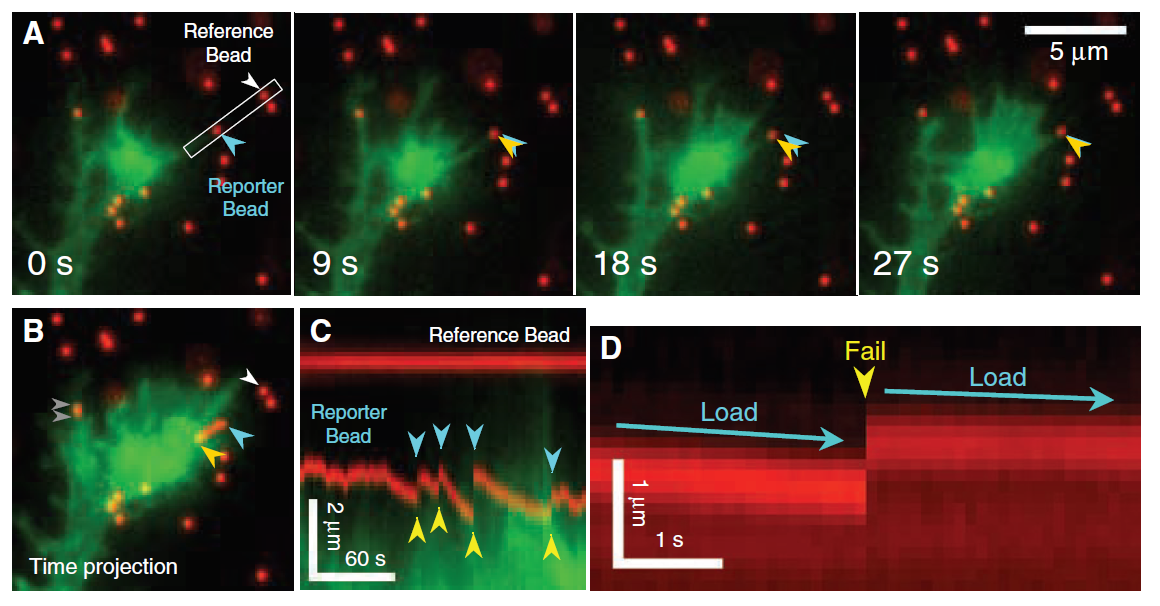

A model is also valuable in interpreting non-intuitive results.  For example, the motor-clutch model predicts non-linear, biphasic behavior of the actin flow rate as a function of substrate stiffness (Figure 5).  This means that in one stiffness range the rate is expected to *decrease* with increasing stiffness, while in others it is expected to *increase* or not change at all.  Therefore, experimentally, one may draw very different conclusions depening on the stiffness range that they were operating in or the cell line that they were using!  When in reality this is a direct prediction from the model that one should expect to observe if the cells are operating via a motor-clutch system.

Figure 5 (from Chan and Odde, *Science*, 2008):

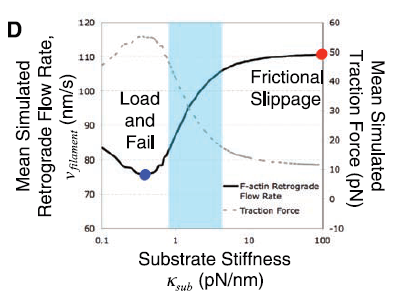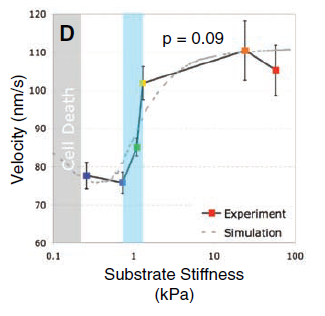

## Cell Migration Simulator

The Odde lab has now taken the motor-clutch model that you coded above and expanded to develop a Cell Migration Simulator (CMS; [Bangasser et al. Nat Comms, 2017](https://www.nature.com/articles/ncomms15313)) (Figure 6).  In the CMS, multiple motor-clutch systems or modules are linked together through a central hub (cell body) and the cell moves as a result of the force balanced between each of the modules (Figure 6 a-b).

Figure 6 (from Bangasser et al., *Nat. Comms*., 2017):

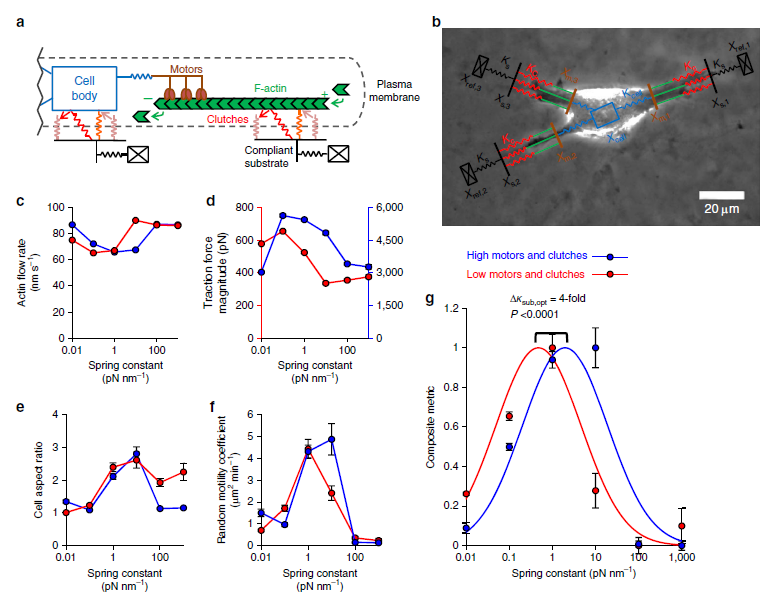

Interestingly, the predictions regarding actin flow rate and traction force made by the 1-dimensional motor-clutch model still hold true for the 2-dimensional Cell Migration Simulator (Figure 6 c-d).  In addition, output from the CMS includes cell morphology and migration, similar to the data contained in the PSON data set for multiple cell lines.  

## Test the predictions experimentally

For the final part of the activity we'll go through the steps that one might take to test model predictions experimentally, using the CMS predictions and the PSON data set to identify an experiment of interest, make a prediction, and then analyze the data.

**Q1.**  **Using the CMS results in Figure 6f above (regarding random motility coefficient, i.e. migration speed), identify a condition**  **or set of conditions from the PSON motility data set that may be used to test the model prediction.**  **Submit your PSON data set condition(s).**

**Q2.**  **Make a hypothesis for a trend you would expect to see in your experimental condition(s) based on the CMS motility results above (Figure 6f).**  **Submit your hypothesis.**

Fill out your answers below and run this section to send your results to Synapse.

my_conditions = '' % Q1 response here

my_hypothesis = '' % Q2 response here

% No need to modify the code below. 
% You'll be prompted to enter your Synapse username and password, 
% then the rest will be taken care of for you.
answers = struct( ...
    'clutchState', csArray, 'substratePosition', subPos, ...
    'conditions', my_conditions, 'hypothesis', my_hypothesis ...
);
[submission, submit_url] = submit_module_answers(answers)

**Next week: **We'll explore how you can use the techniques you've learned in the previous modules to analyze the PSON data set(s) you've chosen in Q1 and Q2 to test  your hypothesis!